%Demo for stability
clc,clear
N=15;

## 公式一 forward 向前传播

I_f=zeros(N,1);
I_f(1)=0.36787944;
for i=1:N-1
    I_f(i+1)=1-(i+1)*I_f(i);
    I_f(i+1)=vpa(I_f(i+1),8);
end
disp(I_f)

   1.0e+03 *

   0.000367879440000
   0.000264241120000
   0.000207276640000
   0.000170893440000
   0.000145532800000
   0.000126803200000
   0.000112377600000
   0.000100979200000
   0.000091187200001
   0.000088127999993
   0.000030592000080
   0.000632895999043
  -0.007227647987559
   0.102187071825826
  -1.531806077387392



## 公式二 backward 向后传播

I_b=zeros(N,1);
I_b(N)=0.042746233;
for n=N-1:-1:1
    I_b(n)=(1-I_b(n+1))/n+1;
end

## 精确解

syms x
I_t=zeros(N,1);
e=exp(1);
for i=1:N
    I_t(i)=int(x^i*e^x,0,1)/e;
end
double(I_t)

ans =    0.367879441171442
   0.264241117657115
   0.207276647028654
   0.170893411885384
   0.145532940573079
   0.126802356561528
   0.112383504069301
   0.100931967445593
   0.091612292989661
   0.083877070103394


## 比较

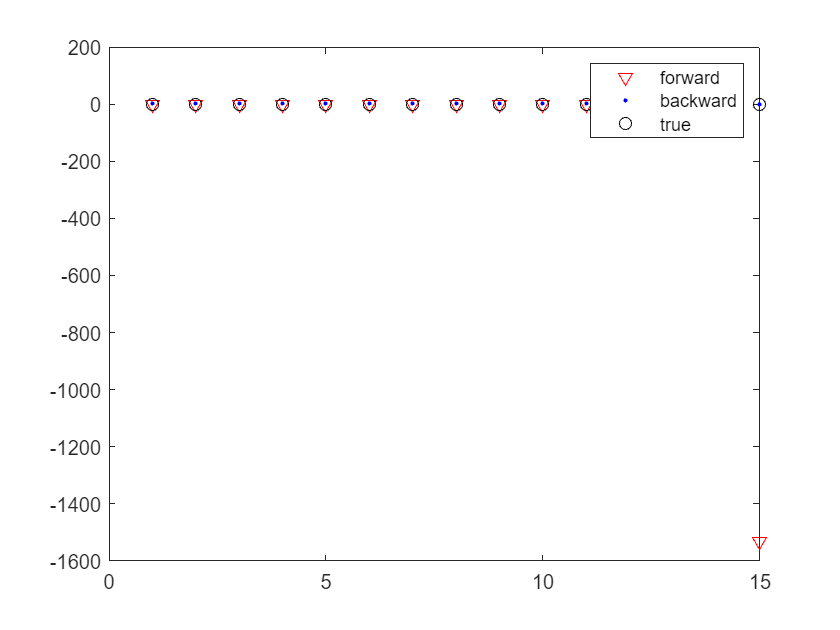

plot(1:N,I_f,'vr',1:N,I_b,'.b',1:N,I_t,'ok')
legend('forward','backward','true');

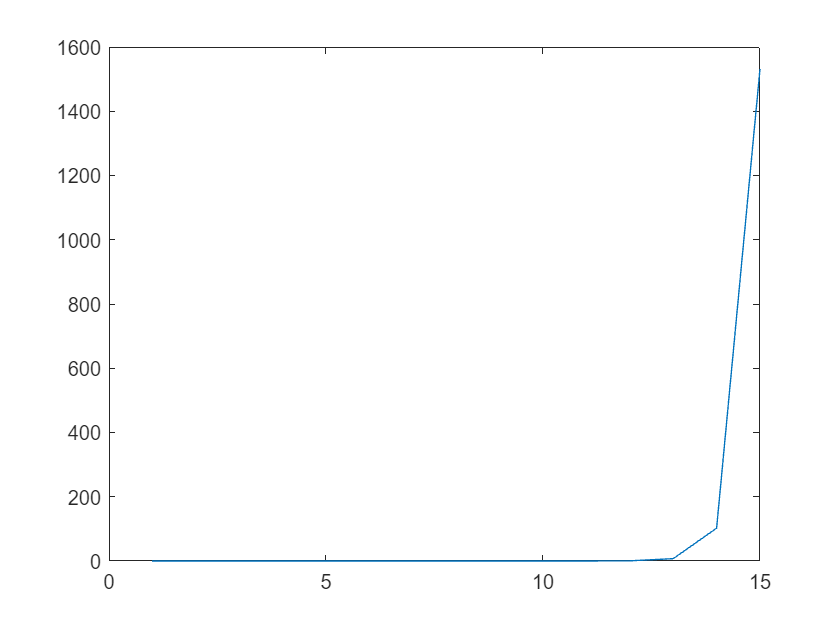

plot(abs(I_t-I_f));

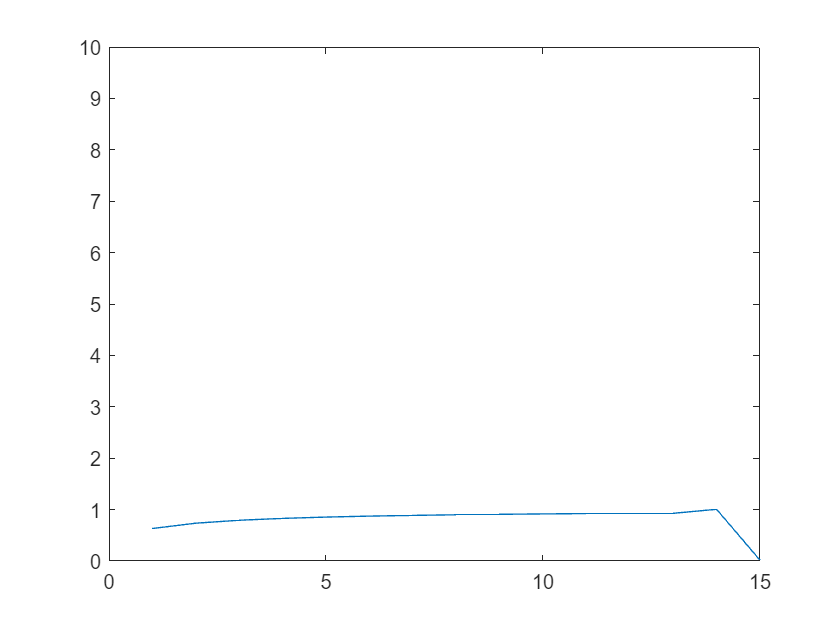

plot(abs(I_t-I_b));
ylim([0,10])